clear all;
clc;
load('raw.mat');

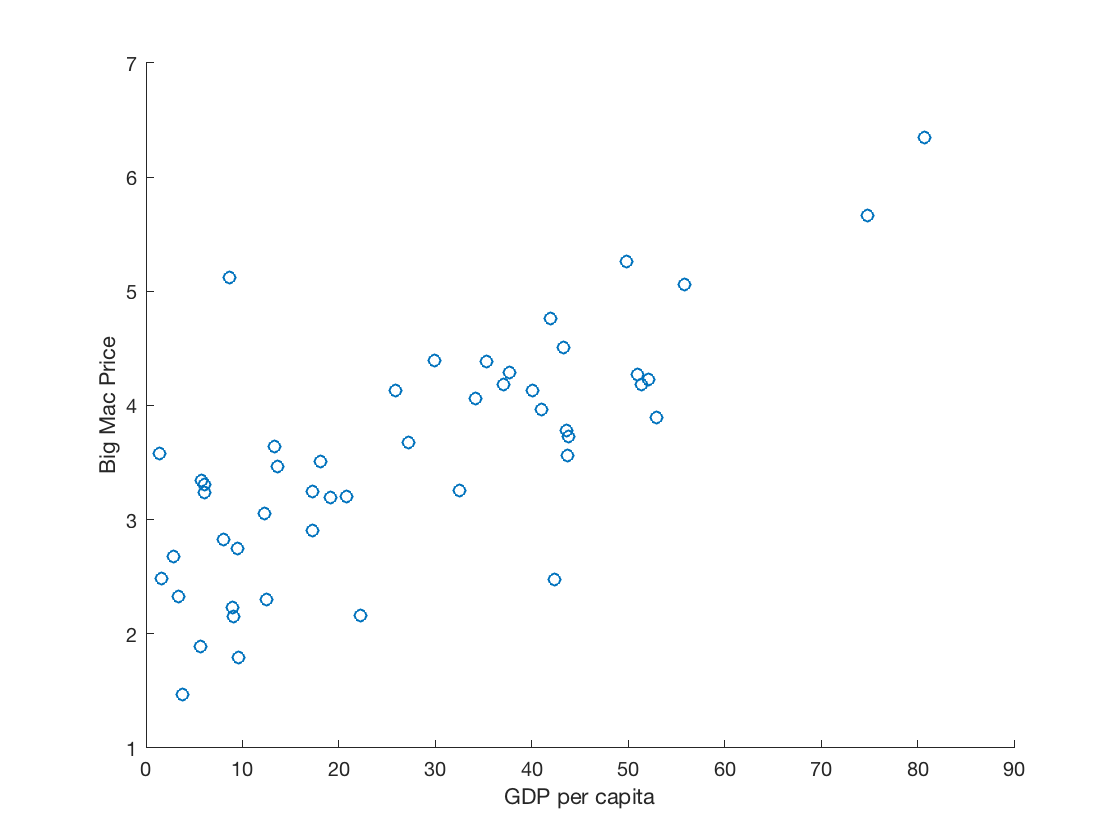

assert(all(~isnan(bigmacjan2017.gdp_pc_usd_2015)));
gdp_1000s = bigmacjan2017.gdp_pc_usd_2015 ./ 1000;
big_mac = bigmacjan2017.dollar_price;
figure;
scatter(gdp_1000s, big_mac);
xlabel 'GDP per capita';
ylabel 'Big Mac Price';

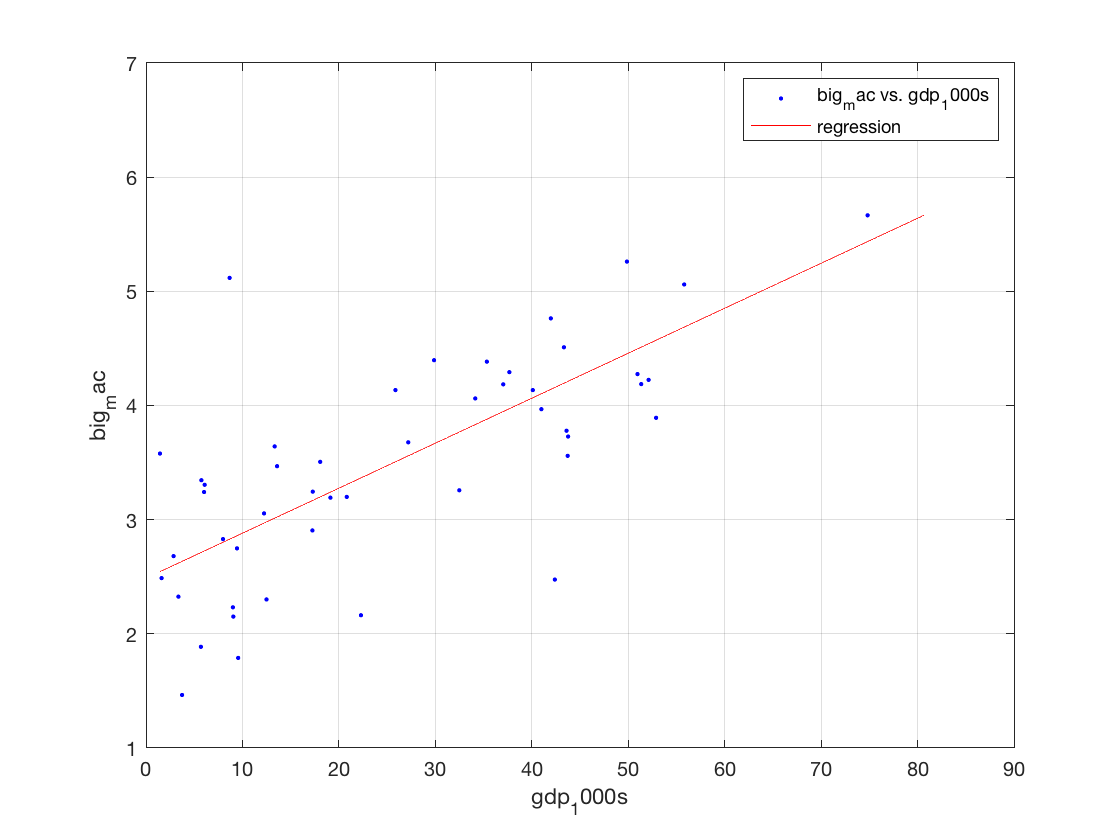

[xData, yData] = prepareCurveData( gdp_1000s, big_mac );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'regression' );
h = plot( fitresult, xData, yData );
legend( h, 'big_mac vs. gdp_1000s', 'regression', 'Location', 'NorthEast' );
% Label axes
xlabel gdp_1000s
ylabel big_mac
grid on

corrcoef([bigmacjan2017.raw_index, bigmacjan2017.adj_index, bigmacjan2017.dollar_price, gdp_1000s])

ans =     1.0000    0.6244    1.0000    0.7582
    0.6244    1.0000    0.6244   -0.0211
    1.0000    0.6244    1.0000    0.7582
    0.7582   -0.0211    0.7582    1.0000


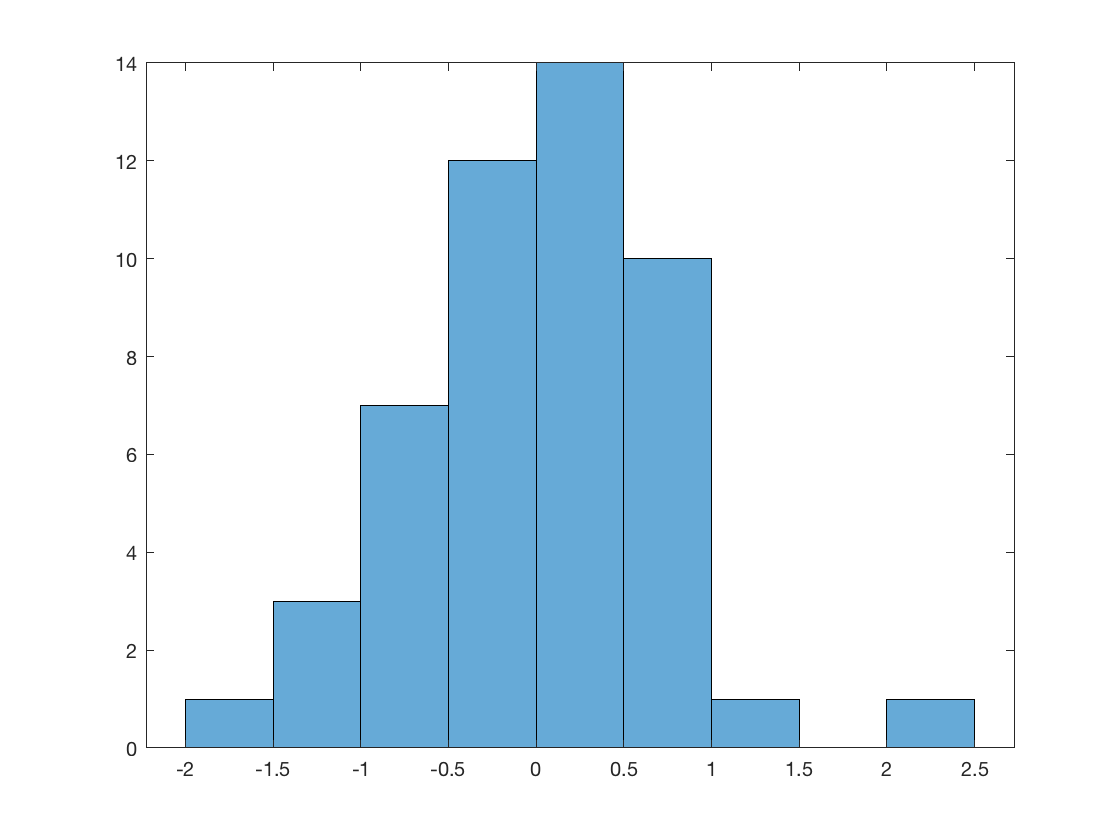

predict = @(xData)(fitresult.p2 + fitresult.p1 .* xData);
error1 = big_mac(1) - predict(gdp_1000s(1));
mean(big_mac - predict(gdp_1000s));
residule = big_mac - predict(gdp_1000s);
histogram(residule);

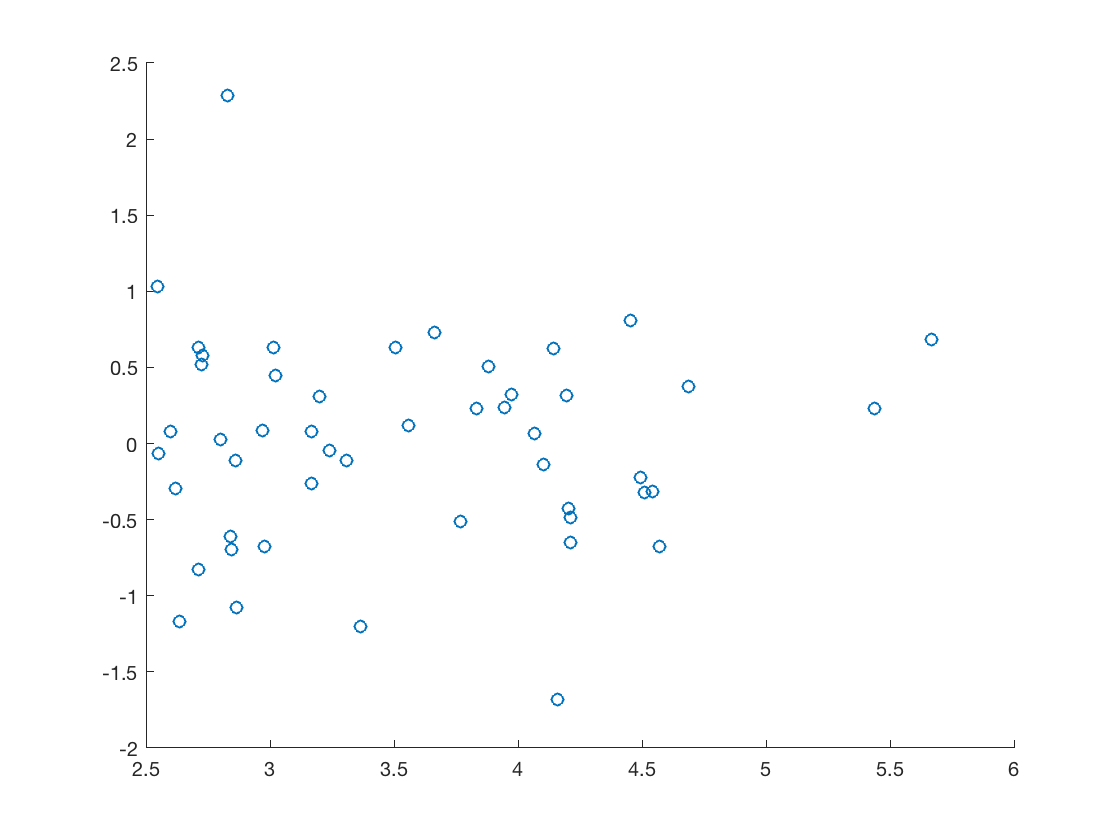

std(residule);
scatter(predict(gdp_1000s), residule);